specs = make_imaging_specs();

mesh_dir = ('/Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes');
solve_bleb_population(mesh_dir, specs);

sys = build_imaging_system(make_imaging_specs());

% Get camera noise

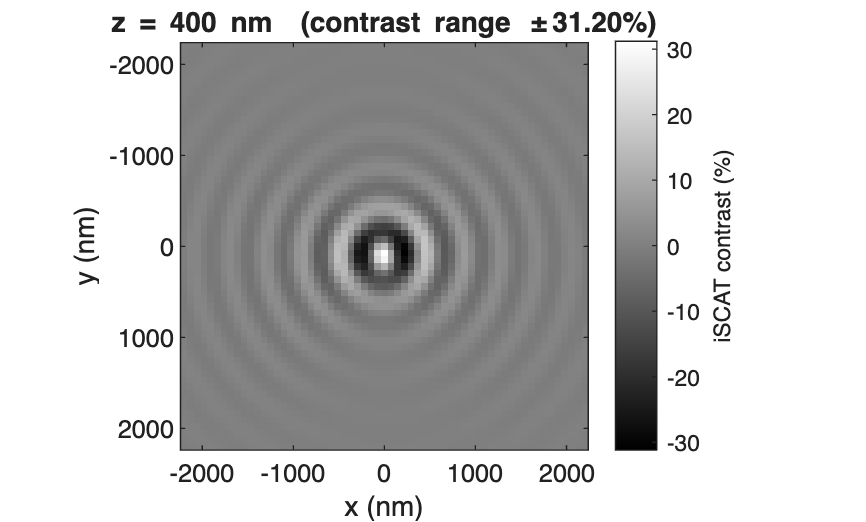

fn = ('/Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/1000LNPSolutions/meshes/bleb_001_mesh.mat');
[mesh, sol] = load_bleb_solution(fn, sys);
z = 400; %nm
lens = sys.lens;
[contrast, im, ibg] = propagate_iscat_image(sol, z, specs, farfields(sol, lens.dir), true);

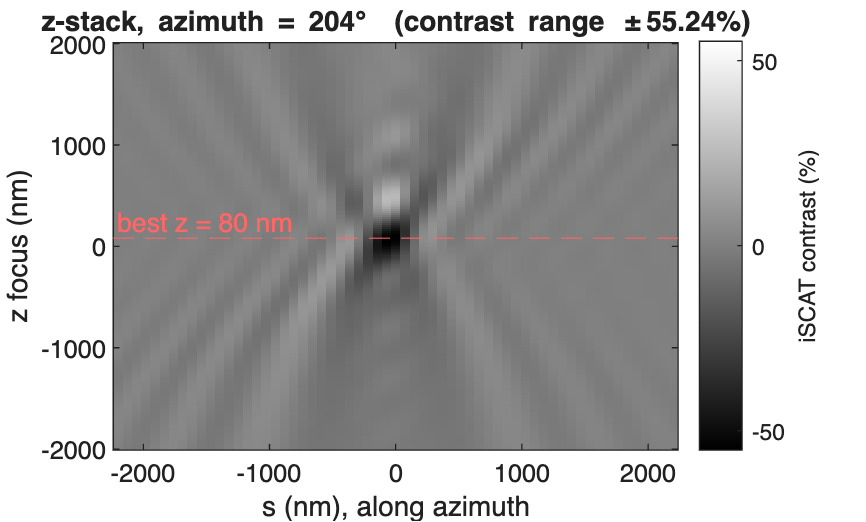

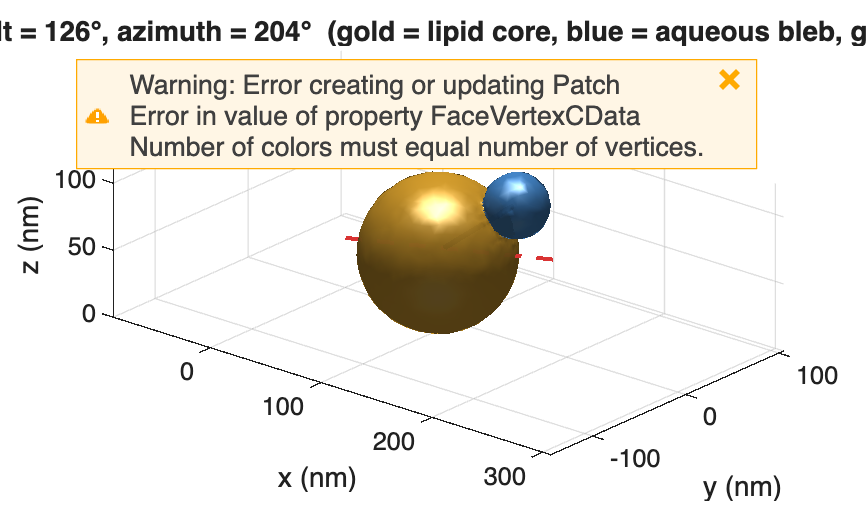

out = propagate_iscat_zstack(mesh, sol, [], sys, -2000:20:2000, true);